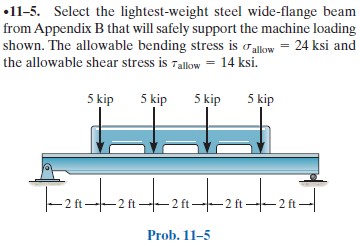

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-5P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-5P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

S = default_struct('reqd', 'design');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -5*u.kip, 2*u.ft);
b = b.add('concentrated', 'force', -5*u.kip, 4*u.ft);
b = b.add('concentrated', 'force', -5*u.kip, 6*u.ft);
b = b.add('concentrated', 'force', -5*u.kip, 8*u.ft);
b = b.add('reaction', 'force', 'Rf', 10*u.ft);
b.L = 10*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(60\,{\mathrm{ft}}^{2}-x^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ \frac{5\,\left(x^{3}+6\,x^{2}\,\mathrm{ft}-132\,x\,{\mathrm{ft}}^{2}+8\,{\mathrm{ft}}^{3}\right)}{6\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ \frac{15\,\left(x^{2}-10\,x\,\mathrm{ft}+4\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{ft}\,\mathrm{kip} & \text{ if }x\in \left(4\,\mathrm{ft},6\,\mathrm{ft}\right]\\ -\frac{5\,\left(x^{3}-36\,x^{2}\,\mathrm{ft}+288\,x\,{\mathrm{ft}}^{2}-288\,{\mathrm{ft}}^{3}\right)}{6\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -\frac{5\,\left(x-10\,\mathrm{ft}\right)\,\left(x^{2}-20\,x\,\mathrm{ft}+40\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(20\,{\mathrm{ft}}^{2}-x^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ \frac{5\,\left(x^{2}+4\,x\,\mathrm{ft}-44\,{\mathrm{ft}}^{2}\right)}{2\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ \frac{30\,\left(x-5\,\mathrm{ft}\right)}{\text{E}\,\text{I}}\,\mathrm{ft}\,\mathrm{kip} & \text{ if }x\in \left(4\,\mathrm{ft},6\,\mathrm{ft}\right]\\ -\frac{5\,\left(x^{2}-24\,x\,\mathrm{ft}+96\,{\mathrm{ft}}^{2}\right)}{2\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -\frac{5\,\left(x^{2}-20\,x\,\mathrm{ft}+80\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 10\,x\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ 5\,\left(x+2\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ 30\,\mathrm{ft}\,\mathrm{kip} & \text{ if }x\in \left(4\,\mathrm{ft},6\,\mathrm{ft}\right]\\ -5\,\left(x-12\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -10\,\left(x-10\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 10\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ 5\,\mathrm{kip} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ 0 & \text{ if }x\in \left(4\,\mathrm{ft},6\,\mathrm{ft}\right]\\ -5\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -10\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 10\,\mathrm{kip}\\ \mathrm{Rf} & 10\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

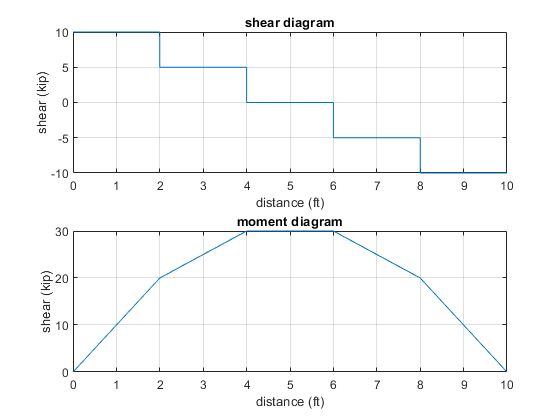

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# maximum loads

M_max = m(4*u.ft)

$$M\_max = 30\,\mathrm{ft}\,\mathrm{kip}$$

V_max = v(0)

$$V\_max = 10\,\mathrm{kip}$$

# required section modulus

sigma_allow = 24*u.ksi;
S.reqd = rewrite(M_max/sigma_allow, u.in);
S_reqd = S.reqd %#ok<NASGU> 

$$S\_reqd = 15\,{\mathrm{in}}^{3}$$

# design section modulus

% ------------------
% - Appendix B table
% ------------------
tbl = beam.appendixB('fps');
Model = tbl.Properties.CustomProperties.Model;
Weight = tbl.Properties.CustomProperties.Weight;
Designation = tbl.Properties.RowNames;
% ---------------------
% - minimum beam weight
% ---------------------
in_range = isAlways(tbl.Sx*u.in^3 >= S.reqd);
Weight_min = symmin(Weight(in_range));
Model_min = Model(Weight == Weight_min & in_range);
min_loc = isAlways(Model == Model_min & ...
                   Weight == Weight_min & ...
                   in_range);
Designation_min = Designation{min_loc}

Designation_min = 'W12 x 16'

% ------------------------
% - design section modulus
% ------------------------
S.design = tbl.Sx(Designation_min)*u.in^3;
S_design = vpa(S.design) %#ok<NASGU> 

$$S\_design = 17.1\,{\mathrm{in}}^{3}$$

# maximum shear stress

tau_allow = 14*u.ksi;
d = tbl.Depth(Designation_min)*u.in;
tw = tbl.Web_Thickness(Designation_min)*u.in;
Aw = d*tw;
tau_max = rewrite(V_max/Aw, u.ksi);
tau_max_vpa = vpa(tau_max, 3) %#ok<NASGU> 

$$tau\_max\_vpa = 3.79\,\mathrm{ksi}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear S_reqd;
clear S_design;
clear tau_max_vpa;